# EEET425 Lab 1 Exploring Signals using MATLAB Live Editor

#### Lab Section 2

#### Team Members

#### Diego Lopez

#### Jonathan Sumner

**Rachel DuBois**

**Argenis Aquino**

#### Team Leader

#### Diego Lopez

**How to Succeed With This Lab**

Before executing the procedure, skim-read through the whole lab handout. 

Answer the questions asked in the procedure in the text portion of this file.

Work together as a team with your lab partners to solve problems and overcome any snags.  Choose a team leader for this lab. The team leader is responsible for delegating tasks, the final report submission and submitting a work breakdown report (who did what) in PDF format.

You will hand in your completed MATLAB Live Script file and a PDF version of the same file.  The PDF version makes it possible for me to comment on your work.  You will also hand in the work breakdown report.

Make sure that you have copied the data file 'Lab1_Signal_Data.mat' into the current working directory.  The current working directory is the file where you started this Live Script from.

**Objectives**

- Understand the concept of linear drift of a signal

- Become familiar with using MATLAB to estimate the linear regression parameters of a signal on a chart

- Become familiar with manipulating signals using MATLAB and its built-in functions

- Use MATLAB to remove the linear drift component of a signal using linear regression

- Use MATLAB to separate the signal and the noise components of a signal

- Estimate the signal power and the noise power then compute the signal to noise ratio.

**Lab Procedure**

#### **Part 1**

Follow the steps in the document and in the code.  I loaded the variable and plotted the first graph for you.  To plot graphs later in the lab use the commands that I used as a template.  Copy and Paste is your friend.

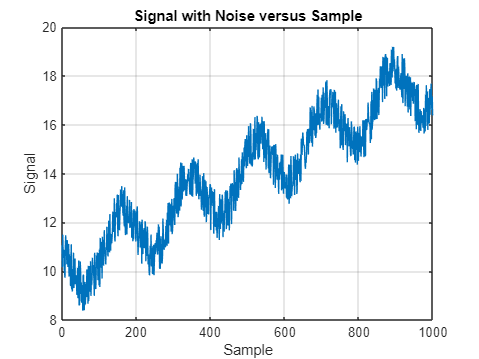

%  Its a good idea to clear all the variables from the workspace before
%  beginning with the MATLAB command <clear>
clear


%  Read in the file from the current directory.  Make sure that the
%  directory you are in is the directory that contains the Lab 1 data file.
%   <pwd> gets the current working directory
pname = pwd;
fname = 'Lab1_Signal_Data.mat';

%  Load in the .mat file containing data for Lab1
%  The data was stored as two variables and will be written into the workspace as those two variables
% 
%  sample -- The sample number
%  signal -- The value of the signal

load(fullfile(pname, fname))

%
%  Plot the signal value versus the sample.  Use this part of the code as a
%  template to copy when making graphs for the rest of the lab.
%

%  !!!!!! Start copying here !!!!!!

figure   %  Create a new figure
plot(sample, signal)  %  Plot the variable signal versus sample

%  Turn on the grid
grid on

%  Title the graph -- Use Descriptive titles
title('Signal with Noise versus Sample')

%  Label the X-axis -- Use Descriptive labels
xlabel('Sample')

%  Label the Y-axis
ylabel('Signal')


% !!!!!  Stop copying here !!!!!


Press the Button below to Run your code in this section

## Questions:

What do you observe about the signal above?  Does it look familiar?  What is different about it?

Type in your answer here

Signal is noisy and drifting

### Comments

The signal looks like it might be sinusoidal, but has some noise on it (the "fuzz" around the signal) and it also has some slow time variation to it as its value is sloping upwards over time.  This continuous change in the signal is referred to as "drift".  Drift can be caused by a number of effects, temperature and power supply voltage changes are just two examples.  

The drift is not part of the signal that we are interested in looking at.  In fact it is a disturbance and part of the noise on the signal.  Because the amount of drift appears to be fairly consistent we can estimate the amount of drift and then actually remove the drift.  The drift in the signal looks to be linear that is the signal is changing at a constant rate over time.

## Part 2  -- Using Linear Regression to Estimate the Drift

### Step 1

Let's use a technique called linear regression to estimate the amount of drift and then remove it from the signal.  You may have seen linear regression in your statistics class.  Linear regression fits the best straight line to the data. 

MATLAB has some built in functions that can be used to compute the best fit line to the data.  It can fit a polynomial of any degree.  We'll just fit a straight line or a polynomial of degree one.

The MATLAB command for fitting a polynomial is polyfit.  The syntax for polyfit is:

coefficients = polyfit(X,Y,N) where Y is the data we are fitting to the variable X.  N is the order of the polynomial.  Linear -- N=1, Quadratic -- N=2 etc.. 

To get help on the polyfit command (or any MATLAB command) just type 

>> help <command> 

at the command window prompt.  For this command especially note how the coefficients are returned.

For a linear fit, the return variable 'coefficients' is actually a 2-dimensional array with the first element being the slope and the second variable being the intercept.

That is: 

slope = coefficients( 1 )

intercept = coefficients( 2 )

Write code below to use the polyfit command to find the best fit line to the drift

%  Use the polyfit command to find the best fit line to the drift 
%
% coefficients = polyfit( sample, signal, 1 );
% slope = 
% intercept = 

%  Solution -- Place your code here

coefficients = polyfit(sample, signal, 1);
slope = coefficients(1)

slope = 0.0080

intercept = coefficients(2)

intercept = 9.9448

Press the Button below to Run your code in this section

### Step 2

Create a variable that is the estimate of the drift from the slope and intercept values of the fitted line.  Recall that the general equation for a line is $y=\textrm{mx}+b$ where m is the slope and b is the intercept.  Create a variable in matlab called <driftEstimate> that represents the y-values of the line.  Use the slope, the sample and the intercept as a part of the equation.  The slope and intercept of the line are the values you computed above using polyfit.

% Place the equation to estimate the drift here
%
%  Just like computing the output of the line y = slope * x + intercept
% driftEstimate = ...
%


%  Solution -- Place your code here

driftEstimate = slope * sample + intercept

driftEstimate =     9.9448
    9.9528
    9.9608
    9.9688
    9.9768
    9.9848
    9.9928
   10.0008
   10.0088
   10.0167


Press the Button below to Run your code in this section

### Step 3

Plot the signal and the fitted line on the same graph

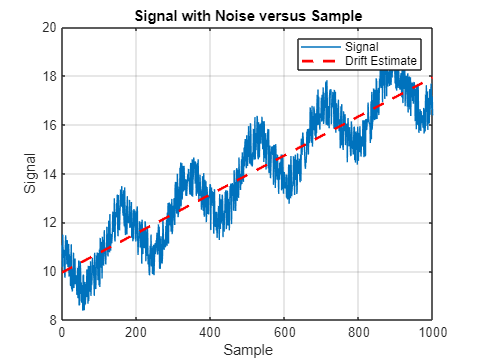

%  Plot both the original data and the best fit line MATLAB graph.  Use the figure command to create a new plot and use the
%  hold command to retain each line on the graph.  You can change line
%  colors widths and styles manually.  If you want MATLAB to do that for
%  you just use the plot command.  For example:
%
%  figure    
%  plot(x,y)
%  grid on
%  hold on
%  plot(x,z,'Color','r','LineWidth',2,'LineStyle','--');%
%
%  Use help plot to find out more options
%  I suggest copying the commands used to create the first graph then
%  modifying them to add the second plot.
%  Add good titles and good labels to the axes accordingly


%  Solution -- Place your code here

figure
plot(sample, signal) % X: sample Y: signal
grid on % Display or hide axes grid lines
hold on % Retain current plot when adding new plots

%  Title the graph -- Use Descriptive titles
title('Signal with Noise versus Sample')
%  Label the X-axis -- Use Descriptive labels
xlabel('Sample')
%  Label the Y-axis
ylabel('Signal')

plot(sample,driftEstimate,'Color','r','LineWidth',2,'LineStyle','--');

% adding legend to show different lines
legend('Signal', 'Drift Estimate')
hold off

Press the Button below to Run your code in this section

## Part 3 -- Remove the Effects of Drift

### Step 1

Now that we have an estimate of the drift we can remove that effect from the signal just by subtracting the fitted line representing the drift from the original signal.  Create a variable called <signalNoDrift> that is the difference between the original signal and the drift.  

%  Place equation to compute the signal without drift  here
%  signalNoDrift = ...

%  Solution -- Place your code here

signalNoDrift = signal - driftEstimate

signalNoDrift =     1.1103
    0.2126
    1.5357
    0.7700
    0.5678
    0.8899
    0.0439
   -0.0562
   -0.2767
    1.0297


Press the Button below to Run your code in this section

### Step 2

On a new figure, plot the original signal, the estimate of the drift and the signal with the drift removed on one plot.  Create a descriptive title and label the x and y axes properly.

Again start with the code that you wrote above to plot both signals and then add a command to plot the third signal with the drift removed.  Copy and Paste is your friend!!

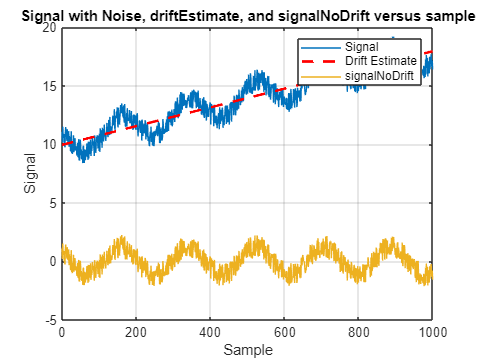

%  Place your code for creating the plot here.  Again copy and paste the
%  previous plot commands to make it easier.  Use different color and line
%  styles as desired or let MATLAB choose them for you
%  

%  Solution -- Place your code here

figure
plot(sample, signal) % Original signal plot
grid on % Display or hide axes grid lines
hold on % Retain current plot when adding new plots

title('Signal with Noise, driftEstimate, and signalNoDrift versus sample') % Custom title

% Axis labels
xlabel('Sample')
ylabel('Signal')

plot(sample,driftEstimate,'Color','r','LineWidth',2,'LineStyle','--'); % Sample versus estimate of drift 
plot(sample,signalNoDrift); % Sample versus signal with no drift

legend('Signal', 'Drift Estimate', 'signalNoDrift') % Legend to show which lines are which
hold off

Press the Button below to Run your code in this section

## Part 4 -- Estimate the Signal 

Often times when we have a signal of interest it also includes noise.  We will use statistics to determine the magnitude of that noise and compare it to the magnitude of the signal. The ratio of those two values is the signal to noise ratio or SNR.  In particular we will take the variance of the noise which is the square of its standard deviation as an estimate of the noise power. 

But what about the signal?  How do we characterize the magnitude of the signal? 

Sometimes the signal that we are interested in is a fixed value or a value that changes very little over the measurement interval.  An example of this might be a signal from a sensor that only changes a small amount over our measurement period.  Another example may be a sinusoidal signal that varies rapidly over our measurement interval.  How we estimate the magnitude of each of these signals will be different.

To estimate the magnitude of the non-changing or slowly varying signal we can simply take the average of that signal as an estimate of the true value of the signal.  

To estimate the magnitude of the sinusoidal signal in noise we have to know something about the frequency and phase of that signal.  There are signal processing approaches that we can use to estimate these values.  However, in this case you will be given the values for the frequency and phase.

### Step 1

For this exercise lets assume that we have estimated what the signal frequency, phase and magnitude is and use that to separate the signal from the noise.

Assume that the parameters of the sinusoid are:

Period, T -- 181.8182 samples (a pretty precise estimate!)

Phase $\phi \;$= 135 degrees

Amplitude A = 1.2

Then the sinusoid has an equation $y = A sin(\frac{2\pi}{T} n+ \frac{\phi}{180} \pi )$  where n is the sample number.

Using MATLAB create a variable <signalEstimate> that is the estimate of the sinusoid by writing an equation for the signal estimate.  Then plot that signal on the same graph as the signal with the drift removed.  Start by creating three variables, one for A, T and phi respectively.  This will help the reader follow your code and make it more flexible if you want to change those values in the future.  What is the value n?

%  Create an estimate the signal
%
%  Create variables for the parameters of the sinusoid
%  A = ...
%  T = ...
%  phi = ...
%
%  Create a variable for the sinusoid estimate 
%
%  signalEstimate = ....

%  Solution -- Place your code here

T=181.8182; % Period
Phi=135; % Phase
A=1.2; % Amplitude
n=sample;
signalEstimate = A*sin( (2*pi/T)*n + (Phi/180*pi))

signalEstimate =     0.8485
    0.8187
    0.7879
    0.7562
    0.7235
    0.6900
    0.6557
    0.6206
    0.5847
    0.5481


Press the Button below to Run your code in this section

### Step 2

Now plot the signal with the drift removed and the estimated signal on the same graph.  Add a title and axes labels.

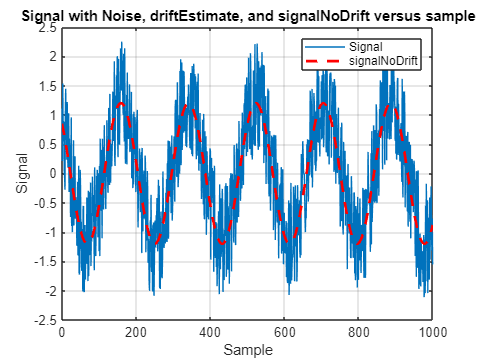

%  Plot the signal with the drift removed and the estimated signal on the
%  same graph
%  


%  Solution -- Place your code here

figure
plot(sample,signalNoDrift) % Sample versus signal with no drift
grid on % Display or hide axes grid lines
hold on % Retain current plot when adding new plots

title('Signal with Noise, driftEstimate, and signalNoDrift versus sample') % Custom title

% Axis labels
xlabel('Sample')
ylabel('Signal')

plot(sample,signalEstimate,'Color','r','LineWidth',2,'LineStyle','--') % Sample versus estimate of drift 
legend('Signal', 'signalNoDrift') % Legend to show which lines are which
hold off

Press the Button below to Run your code in this section

## Part 5 -- Estimate the noise signal

### Step 1

Now that we have a pretty good estimate of the signal, we can remove the signal from the noise leaving and estimate of the noise signal.  Then we can estimate the power of the noise using the variance.

Create a variable <noise> by taking the difference between the signal with the drift removed and subtracting the signal estimate.  Plot this value versus the sample.

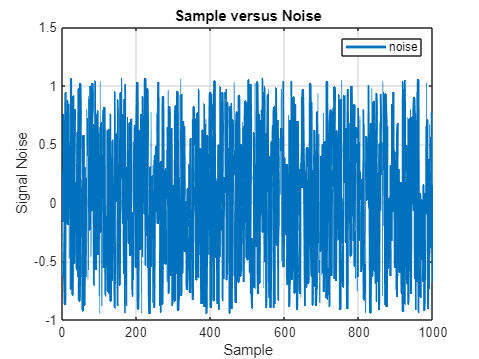

% Create an estimate of the noise and plot the noise estimate on a graph by
% itself
%
%  noise = ...


%  Solution -- Place your code here

noise = signalNoDrift - signalEstimate;

figure
plot(sample,noise,'LineWidth',2) % Sample versus estimate of drift 
grid on % Display or hide axes grid lines
hold on % Retain current plot when adding new plots

title('Sample versus Noise') % Custom title

% Axis labels
xlabel('Sample')
ylabel('Signal Noise')

legend('noise') % Legend to show which lines are which
hold off

Press the Button below to Run your code in this section

## Part 6  Estimate the noise power and signal to noise ratio

### Step 1

Calculate the noise power by taking its variance.  MATLAB does have a variance <var> command but we can also use the command for standard deviation and square it to get the variance.  The MATLAB command for standard deviation is <std>.

Calculate the variance of a few other signals to compare:

- Variance of the original signal --- varOrig

- Variance of the signal with the drft removed -- varNoDrift

- Variance of the estimated sinusoidal signal -- varSignal

- Variance of the noise -- varNoise

% Compute the variance of the signals by taking the square of the standard
% deviation of the signal.
%
% varOrig = 
% varNoDrift = 
% varSignal = 
% varNoise = 
%

%  Solution -- Place your code here

varOrig = var(signal)

varOrig = 6.3632

varNoDrift = var(signalNoDrift)

varNoDrift = 1.0328

varSignal = var(signalEstimate)

varSignal = 0.7184

varNoise = var(noise)

varNoise = 0.3342

Press the Button below to Run your code in this section

### Step 2

Then calculate the signal to noise ratio (SNR) of the desired sinusoid and the noise.  Since we are using variances which are squared values of magnitude, these represent power (Hint:  Think of the power of an electrical  signal dissipated in a resistor $P=\frac{E^2 }{R}$).  When we compute the SNR in decibels in this case we are taking the ratio of powers so the SNR in decibels is


$${\textrm{SNR}}_{\textrm{dB}} =10\log_{10} \left({\textrm{SNR}}_{\textrm{num}} \right)=10\log_{10} \left(\;\frac{\left(\textrm{Signal}\;\textrm{Variance}\right)}{\left(\textrm{Noise}\;\textrm{Variance}\right)}\right)$$


%  Compute the signal to noise ratio numerically and in decibels
%
%  snrNum =   %  The numerical signal to noise ratio (SNR)
%  snrDb =    %  The signal to noise ration (SNR) in decibels

%  Solution -- Place your code here

snrNum = varSignal / varNoise

snrNum = 2.1497

snrDb = 10*log10(snrNum)

snrDb = 3.3239

Press the Button below to Run your code in this section

### Step 3

Display the values using a table in MATLAB

Use the 'table' function in MATLAB.   I've created the  table for you this time.  You can use this as a template to create later tables.  Use the help feature of MATLAB to look up how to enter values in a table.  The values of a column must be a column vector.  Use the Properties 'RowName' and 'VariableNames' to add row names and column names respectively.  Note that the list of row names and variable names must be a MATLAB cell array which is a data type that is enclosed by curly braces.  For example a = { 'first', 'second', 'third'} is a cell array.

If you used the variable names that I used above, this should work OK.  Modify the following code as necessary

% Create a column vector with the values for the table.
% Each value for the statistics is in one row.
%  Recall that placing a semicolon (instead of a space or comma) between
%  values creates a column vector.

valuesForTable = [varOrig; varNoDrift; varSignal; varNoise; snrNum; snrDb];

%  Create the table.  Add Row Names and a Name for the column of values

statsTable = table(valuesForTable,...
    'RowNames',{'Original Variance','No Drift Variance','Estimated Signal Variance','Noise Variance','SNR (numerical)','SNR (dB)'},...
    'VariableNames',{'Values'})

statsTable = 6×1 table
                                 Values 
                                 _______

    Original Variance             6.3632
    No Drift Variance             1.0328
    Estimated Signal Variance    0.71839
    Noise Variance               0.33418
    SNR (numerical)               2.1497
    SNR (dB)                      3.3239


Press the Button below to Run your code in this section

## Part 6 Write your output to an PDF file

Make sure that you add your lab section to the top of this file.  Add all the names of the team members to the file and the name of the team leader.

Export the completed file with all of the graphs properly titled and labeled as a PDF file.  Use Save\Export as PDF from the tool bar.

Open the PDF file and make sure that it includes everything in this file.  Sometimes there are rendering problems and I have had best luck with saving the file first as a Word file and then saving the Word file as a PDF.

Upload both this completed Live Script file and the PDF file to Assignments section of myCourses.